# Sprawozdanie z zajęć laboratoryjnych nr 5 i 6 - stanowisko wahadła reakcyjnego

## Strojenie regulatora LQR

#### Dawid Lisek

#### Paweł Mańka

Poniedziałek 8.00 20.11.2023

Po skorzystaniu z narzędzia Model Linearizer dostępnego w pakiecie Simulink zostały wygenerowane macierze stanu opisujące symulacyjny model wahadła reakcyjnego w dolnym położeniu równowagi.

A = linsys1_dolne.A

A =          0    1.0000         0
   -4.9764   -1.1417    0.0145
         0         0   -1.1309


B = linsys1_dolne.B

B =          0
   -5.2369
  488.6480


C = linsys1_dolne.C

C =      1     0     0
     0     1     0
     0     0     1


D = linsys1_dolne.D

D =      0
     0
     0


eig(A)

ans =   -0.5709 + 2.1565i
  -0.5709 - 2.1565i
  -1.1309 + 0.0000i


Następnie sprawdziliśmy wartości własne układu bez regulatora LQR. Z powyższych wartości własnych wynika, że jest to stabilny układ oscylacyjnie tłumiony, ponieważ posiada jedną parę sprzężoną oraz części rzeczywiste wartości własnych są ujemne.

co = ctrb(A, B)

co =          0   -5.2369   13.0867
   -5.2369   13.0867    3.0816
  488.6480 -552.6005  624.9228


co_rank = rank(co)

co_rank = 3

Układ jest również sterowalny, ponieważ rząd macierzy sterowalności jest równy jej wymiarowi.

Następnie przystąpiliśmy do tworzenia regulatora LQR.

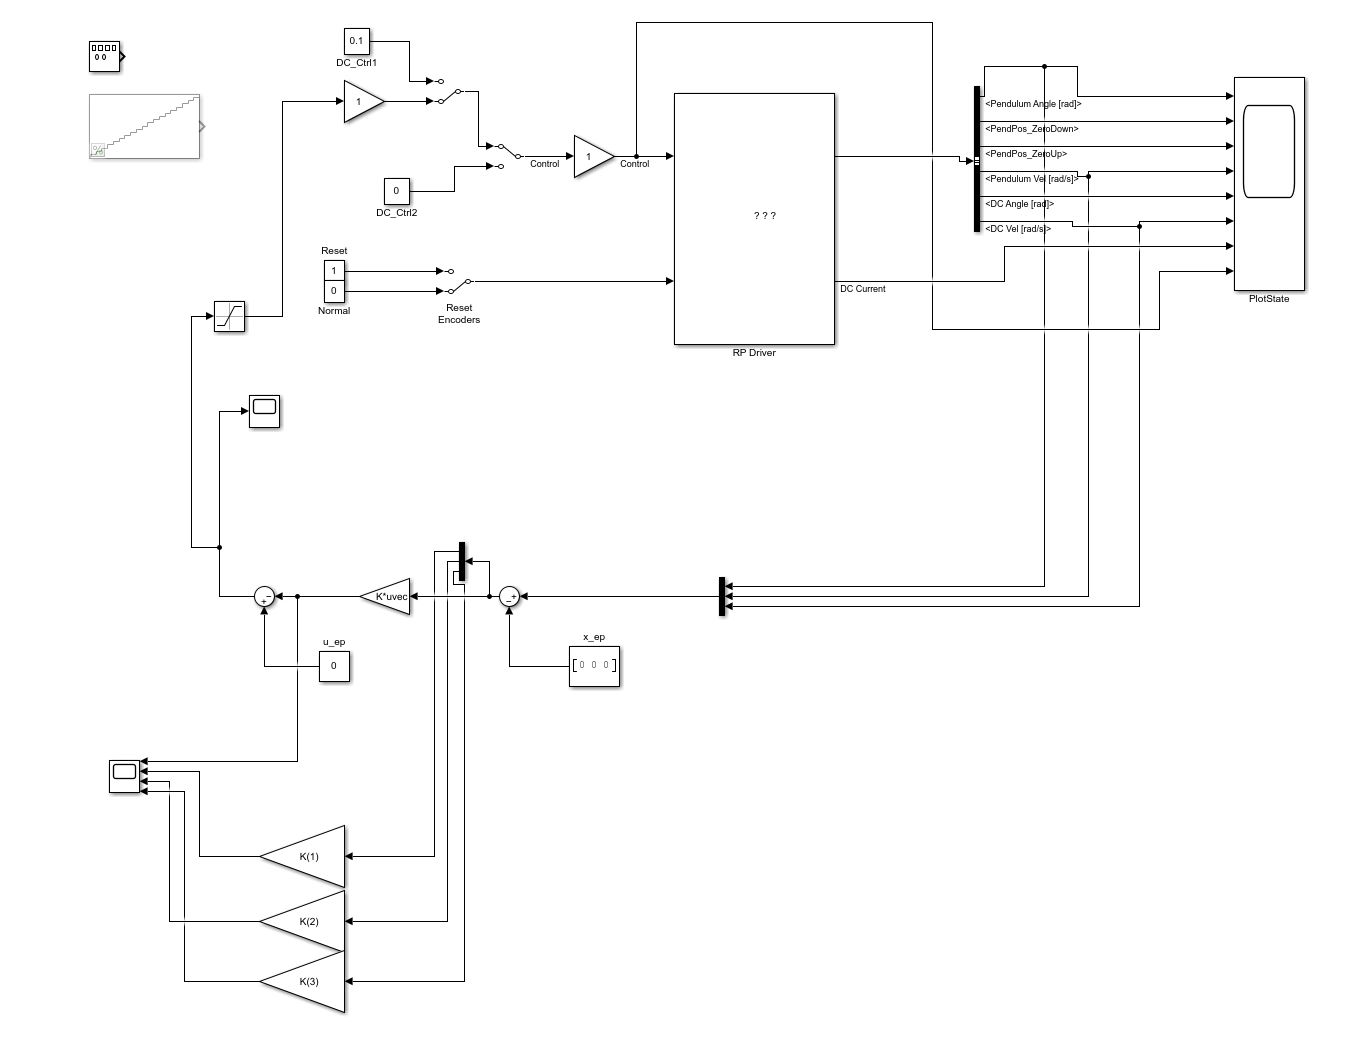

 Wzmocnienia regulatora LQR zostały wyznaczone przy pomocy funkcji lqr() dostępnej w Matlabie.

Q = eye(3)

Q =      1     0     0
     0     1     0
     0     0     1


R = 1

R = 1

[K, S, E] = lqr(A, B, Q, R)

K =    -0.0278   -0.0041    0.9977


S =     2.7316    0.1004    0.0010
    0.1004    0.5259    0.0056
    0.0010    0.0056    0.0021


E = 	1.0e+02 *

  -4.8868 + 0.0000i
  -0.0057 + 0.0216i
  -0.0057 - 0.0216i


Przypadkowe nastawy regulatora LQR nie przynosiły porządanych efektów, więc posłużyliśmy się regułą Brysona dzięki, której udało nam się przeprowadzić poprawne strojenie regulatora. Reguła Brysona mówi, że element leżący na diagonali macierzy Q powinien być równy odwrotności kwadratu maksymalnej akceptowalnej wartości zmiennej stanu.

Elementy leżące na diagonali macierzy R powinny być równe odwrotności kwadratu maksymalnej akceptowalnej wartości sterowania pochodzącej od danej zmiennej stanu.

W nawiązaniu do tej reguły napisane zostały poniższe macierze Q oraz R

Q = [100 0 0; 0 10 0; 0 0 1/1000]

Q =   100.0000         0         0
         0   10.0000         0
         0         0    0.0010


R = 15

R = 15

[K, S, E] = lqr(A, B, Q, R)

K =    -1.9606   -0.4539    0.0072


S =    51.8054    4.2540   -0.0146
    4.2540    6.7516    0.0584
   -0.0146    0.0584    0.0008


E =   -5.0142 + 0.0000i
  -1.5820 + 1.2876i
  -1.5820 - 1.2876i


Jak widać układ nadal posiada dwie urojone wartości własne sprzężone, więc jest oscylacyjnie tłumiony. Dodatkowo obliczone zostało tłumienie układu.

ksi = abs(real(E(2)))/abs(E(2))

ksi = 0.7756

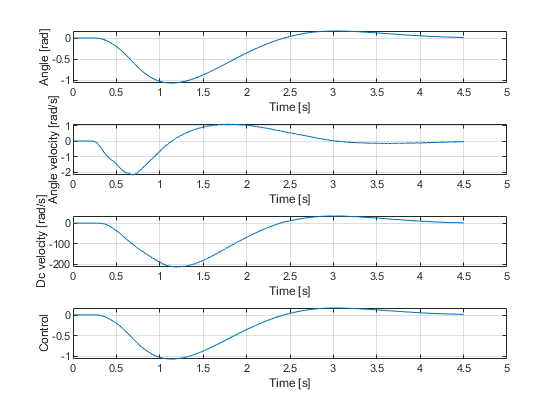

pomiary = test3_stan_oscylacyjny;
time = pomiary.time;
angle = pomiary.signals(1).values;
angle_vel = pomiary.signals(4).values;
dc_vel = pomiary.signals(6).values;
control = pomiary.signals(8).values;

angle = angle(1450:1900);
time = time(1450:1900) - time(1450);
angle_vel = angle_vel(1450:1900);
dc_vel = dc_vel(1450:1900);
control = control(1450:1900);

figure('Name','Oscylacyjny')
subplot(4, 1, 1)
plot(time, angle)
xlabel('Time [s]')
ylabel('Angle [rad]')
% subtitle("Wychylenie wahadła")
grid on
subplot(4, 1, 2)
plot(time, angle_vel)
xlabel('Time [s]')
ylabel('Angle velocity [rad/s]')
% subtitle("Prędkość kątowa wahadła")
grid on
subplot(4, 1, 3)
plot(time, dc_vel)
xlabel('Time [s]')
ylabel('Dc velocity [rad/s]')
% subtitle("Prędkość silnika")
grid on
subplot(4, 1, 4)
plot(time, angle)
xlabel('Time [s]')
ylabel('Control')
% subtitle("Sterowanie")
grid on

Układ posiada delikatne przesterowanie, które jest spowodowane jego oscylacyjnym charakterem.

Q = [300 0 0; 0 50 0; 0 0 1/1000]

Q =   300.0000         0         0
         0   50.0000         0
         0         0    0.0010


R = 15

R = 15

[K, S, E] = lqr(A, B, Q, R)

K =    -4.1293   -1.2095    0.0085


S =   160.5055    4.4442   -0.0791
    4.4442   16.1800    0.1363
   -0.0791    0.1363    0.0017


E =    -9.7735
   -1.6280
   -1.3391


ksi = abs(real(E(2)))/abs(E(2))

ksi = 1

Powyższy układ posiada rzeczywiste wartości własne dzięki którym jest asymptotycznie stabilny. Współczynnik tłumienia jest równy 1 ze względu na brak części urojonej pierwiastków.

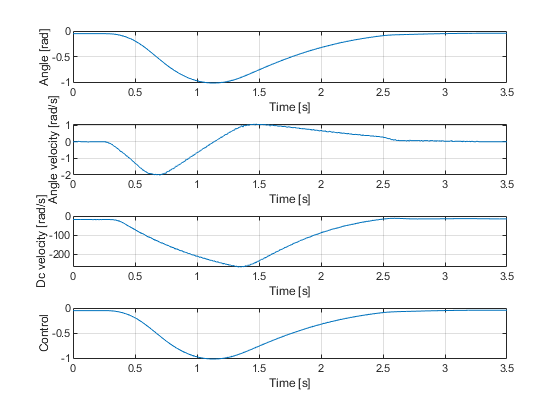

pomiary = test1_stan_aperiodyczny;
time = pomiary.time;
angle = pomiary.signals(1).values;
angle_vel = pomiary.signals(4).values;
dc_vel = pomiary.signals(6).values;
control = pomiary.signals(8).values;

angle = angle(3190:3540);
time = time(3190:3540) - time(3190);
angle_vel = angle_vel(3190:3540);
dc_vel = dc_vel(3190:3540);
control = control(3190:3540);

figure('Name','Aperiodyczny')
subplot(4, 1, 1)
plot(time, angle)
xlabel('Time [s]')
ylabel('Angle [rad]')
% subtitle("Wychylenie wahadła")
grid on
subplot(4, 1, 2)
plot(time, angle_vel)
xlabel('Time [s]')
ylabel('Angle velocity [rad/s]')
% subtitle("Prędkość kątowa wahadła")
grid on
subplot(4, 1, 3)
plot(time, dc_vel)
xlabel('Time [s]')
ylabel('Dc velocity [rad/s]')
% subtitle("Prędkość silnika")
grid on
subplot(4, 1, 4)
plot(time, angle)
xlabel('Time [s]')
ylabel('Control')
% subtitle("Sterowanie")
grid on

Dzięki temu, że układ w zamkniętej pętli sterowania jest aperiodycznie stabilny możemy zaobserwować całkowity brak przeregulowania, które występowało w układzie oscylacyjnym.

Następnym krokiem było zaimplementowanie regulatora LQR w górym położeniu wahadła. W tym celu ponownie przystąpiliśmy do linearyzacji modelu.

A = linsys1_gorne.A

A =          0    1.0000         0
    4.9764   -1.1417    0.0145
         0         0   -1.1309


B = linsys1_gorne.B

B =          0
   -5.2369
  488.6480


C = linsys1_gorne.C

C =      1     0     0
     0     1     0
     0     0     1


D = linsys1_gorne.D

D =      0
     0
     0


Różnica w obydwu modelach polega tylko na zmianie znaku w części macierzy A odpowiadającej za moment pochodzący od siły grawitacji wahadła.

Macierz Q, R oraz wzmocnienia regulatora LQR wynoszą:

Q = [100 0 0; 0 10 0; 0 0 1/1000]

Q =   100.0000         0         0
         0   10.0000         0
         0         0    0.0010


R = 15

R = 15

[K, S, E] = lqr(A, B, Q, R)

K =    -8.4592   -2.9173   -0.0150


S =   311.9907   97.7984    0.7884
   97.7984   34.1298    0.2762
    0.7884    0.2762    0.0025


E =    -5.9886
   -3.1002
   -1.1237


Warto zauważyć że dla identycznej macierzy Q oraz R w dolnym położeniu wahadła układ miał charakter oscylacyjnie tłumiony, zaś w górym położeniu układ jest asymptotycznie stabilny.

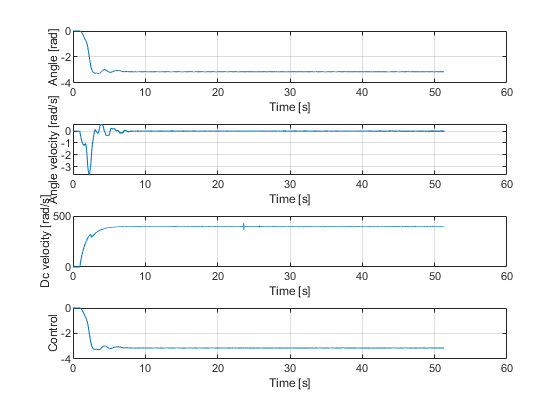

pomiary = test6_wahadlo_pionowe;
time = pomiary.time;
angle = pomiary.signals(1).values;
angle_vel = pomiary.signals(4).values;
dc_vel = pomiary.signals(6).values;
control = pomiary.signals(8).values;

angle = angle(430:end);
time = time(430:end) - time(430);
angle_vel = angle_vel(430:end);
dc_vel = dc_vel(430:end);
control = control(430:end);

figure('Name','Aperiodyczny')
subplot(4, 1, 1)
plot(time, angle)
xlabel('Time [s]')
ylabel('Angle [rad]')
% subtitle("Wychylenie wahadła")
grid on
subplot(4, 1, 2)
plot(time, angle_vel)
xlabel('Time [s]')
ylabel('Angle velocity [rad/s]')
% subtitle("Prędkość kątowa wahadła")
grid on
subplot(4, 1, 3)
plot(time, dc_vel)
xlabel('Time [s]')
ylabel('Dc velocity [rad/s]')
% subtitle("Prędkość silnika")
grid on
subplot(4, 1, 4)
plot(time, angle)
xlabel('Time [s]')
ylabel('Control')
% subtitle("Sterowanie")
grid on

Układ działa poprawnie i zapewnia stabilizację w górnym położeniu wahadła. 

#### Podsumowanie oraz wnioski:

Podczas zajęć laboratoryjnych przeprowadziliśmy proces strojenia regulatora LQR na fizycznym obiekcie. Mogliśmy zaobserwować jak zmienia się charakter pracy układ podczas zmiany jego wartości własnych. Ważnym aspektem w czasie całego ćwicznia było zauważenie powiązania pomiędzy wartościami własnymi naszego układu, a jego fizycznymi parametrami. Dzięki temu udało nam się zmienić układ oscylacyjnie tłumiony w układ asympotycznie stabilny, który nie posiada przeregulowania.     